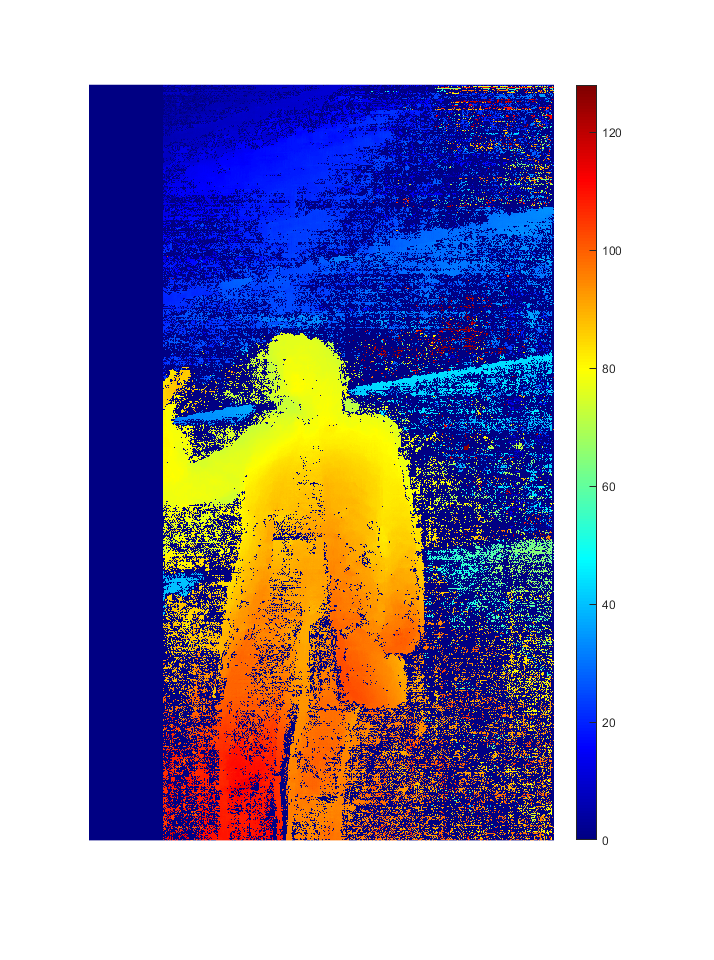

left = rgb2gray(imread("0002_L.png"));
right = rgb2gray(imread("0002_R.png"));
disparityRange = [0 128];
uniq = 10;
dispMap1 = disparitySGM(left,right, "DisparityRange", disparityRange, 'UniquenessThreshold',uniq);
%disparityRange = [-128 0];
dispMap2 = disparitySGM(flip(right,2),flip(left,2), "DisparityRange", disparityRange, 'UniquenessThreshold',uniq);



%imshow(dispMap1)
figure;
imshow(dispMap1, disparityRange)
colormap jet
colorbar

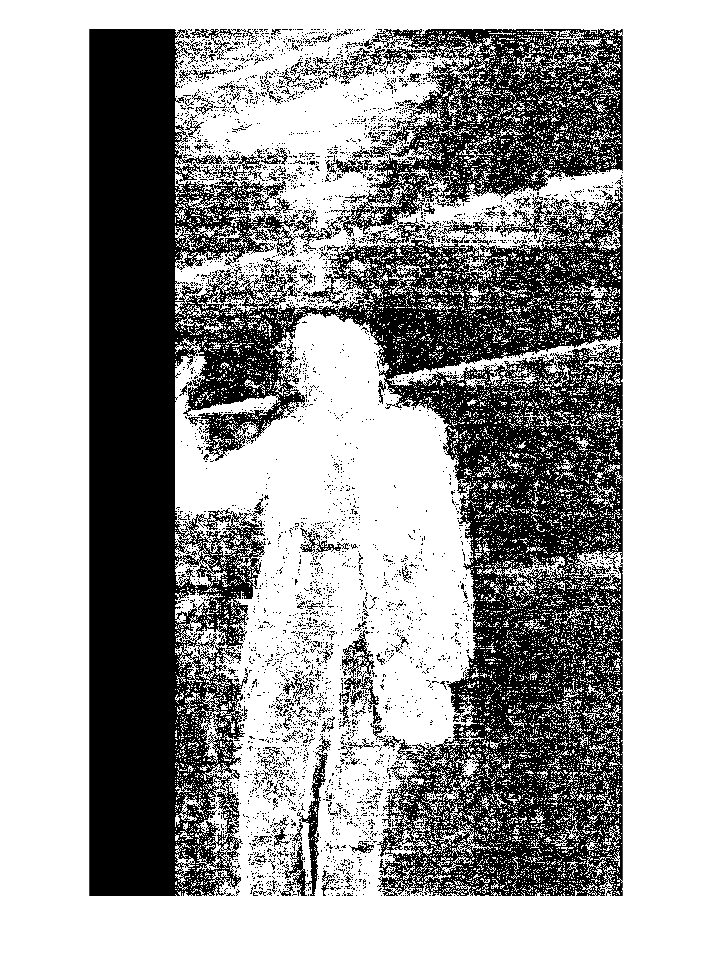

threshhold = 60;

%😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂
mask = dispMap1;


mask(mask ~= mask) = 0;
imshow(mask)

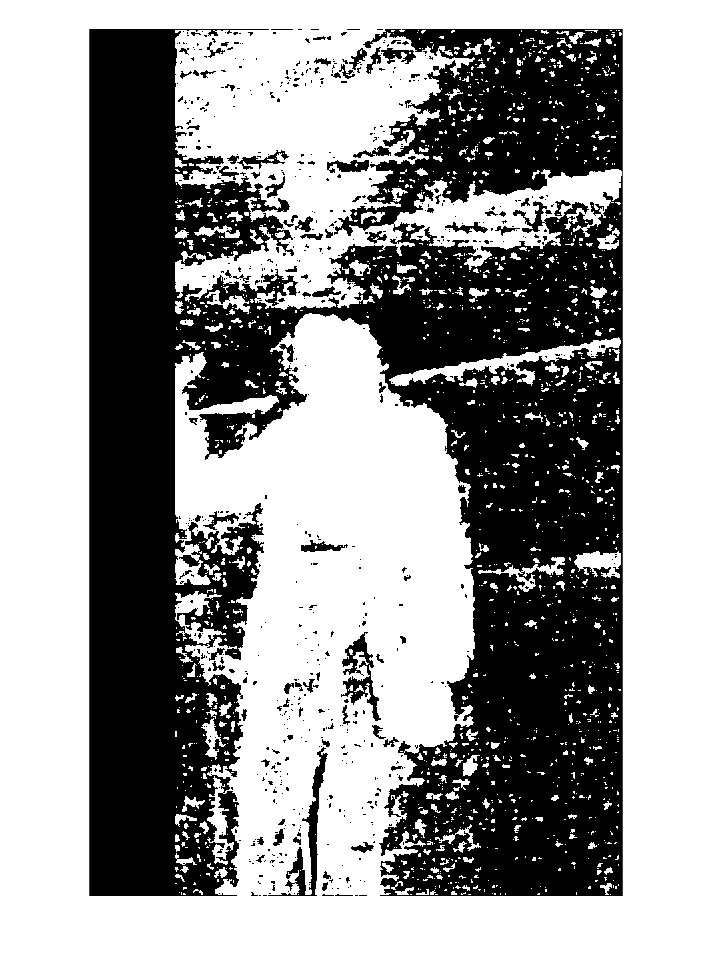

mask = medfilt2(mask,[5 5]);
imshow(mask)

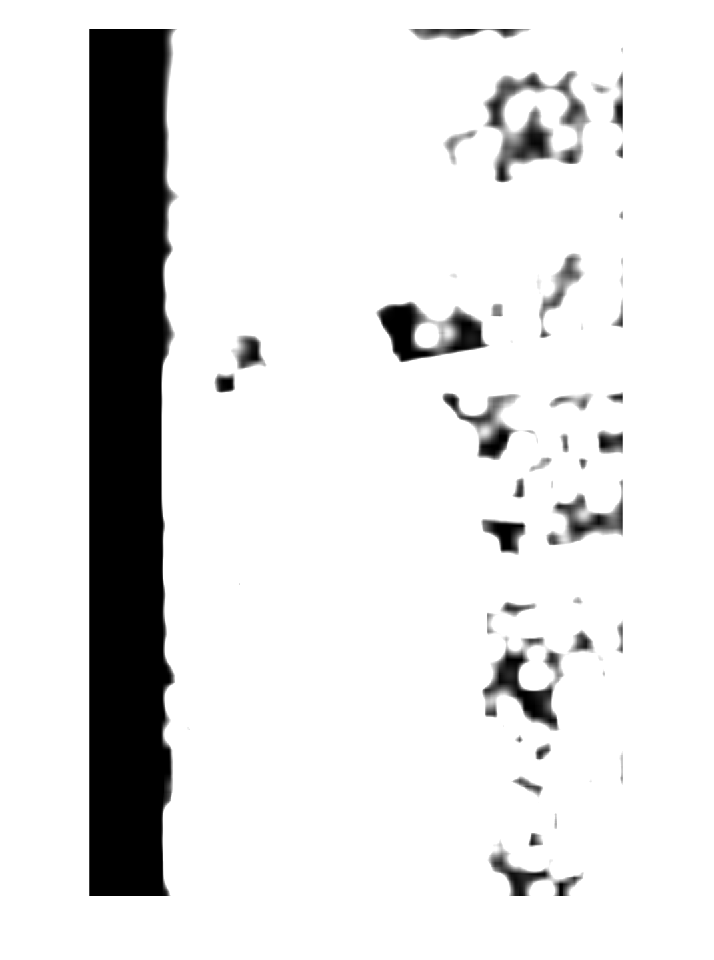

mask = imgaussfilt(mask,10);
imshow(mask)

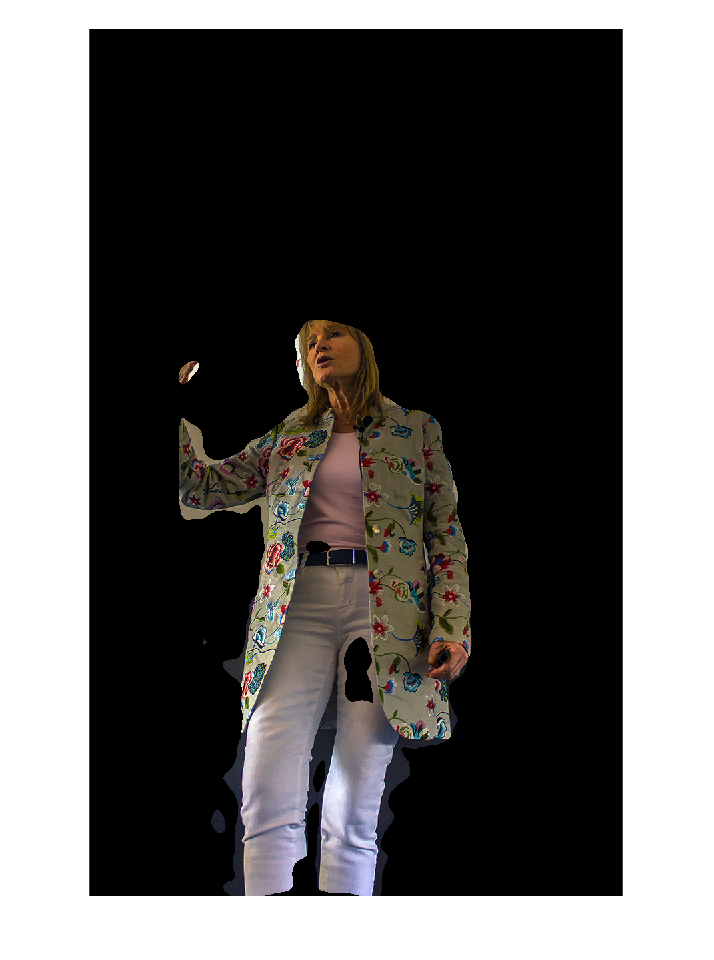


mask(mask < threshhold) = 0;
mask(mask >= threshhold) = 1;
%😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂😂

live = imread('0002_L.png');
for i = 1:3
    live(:,:,i) = immultiply(uint8(mask),live(:,:,i));
end

imshow(live)